clear;
clc;

## Scenario Setup

Describe physical parameters (Load from Base Scenario file)

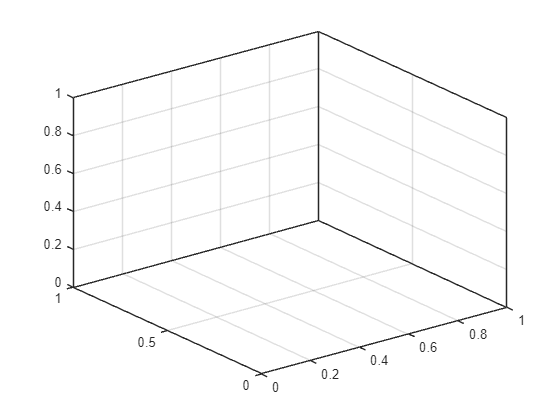

ScenarioBase();

%For Graphing
GraphZBW = [];
GraphXTime = [];
GraphYSimple = [];
GraphYMaxAoI= [];
GraphYMAB = [];
hold on;
view(3);
grid on;
box on;

## Execute Scenario

Prepare Sim: Assume Fixed Delay; no relays, no bandwidth variance

TDelayAtStep = DelayPhysDist;

Generate Items (command sent at $t=0$ so sim starts after delay)

ItemList(1) = Item("Photo", 0,  3, 6 * TimeStep, TimeStep * 10);
ItemList(2) = Item("Video", 0,  9, 12 * TimeStep, TimeStep * 2);
ItemList(3) = Item("Loc",   0, 10, 1 * TimeStep, TimeStep);
ItemList(4) = Item("Stats", 0,  5, 3 * TimeStep, TimeStep * 5);
ItemList(5) = Item("LIDAR", 0,  9, 8 * TimeStep, TimeStep * 2);

for i=6:MaxItems
    ItemList(i) = Item(i, 0, rand()*10,  (BRMax * rand()/2) * TimeStep, TimeStep * rand() * 10);
end

ItemCount = numel(ItemList);

At $t=0$ we received a command on the Moon, updates will now start sending from Moon to Earth

Here, we loop through different values of available bandwidth in order to test against increasingly constrained scenarios.

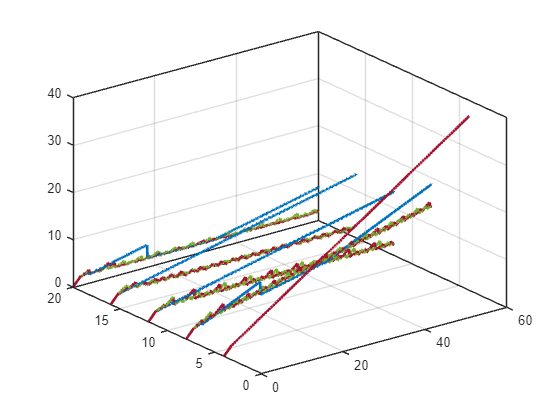

for CurrBR=BRMin:BRStep:BRMax
    BRPerStep = CurrBR * TimeStep;
    % First-Update-First-Serve (Simple) Method
    SendSimple();
    % Max(AoI) Method
    SendMaxAoI();
    % MAB Method
    SendMAB();

    % For Graphing
    BWAxis = ones(1, Iter-1) * CurrBR;
    plot3(LoggedXTime, BWAxis, LoggedYAoSSimple, '-', Color="#0072BD", LineWidth=2);
    plot3(LoggedXTime, BWAxis, LoggedYAoSMaxAoI, '-', Color="#77AC30", LineWidth=2);
    plot3(LoggedXTime, BWAxis, LoggedYAoSMAB, '-', Color="#A2142F", LineWidth=2);
end

**Finish Graphing**

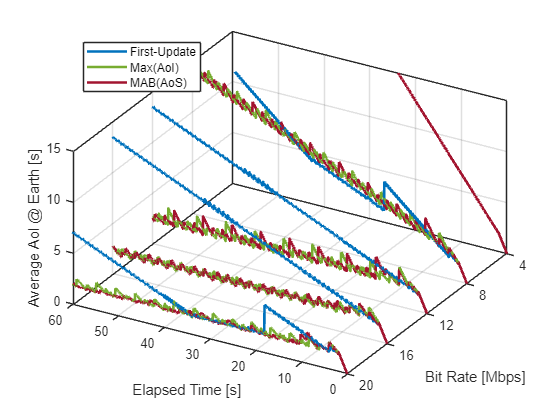

% title("Algorithm Performance with Varying Bandwidth");
xlabel("Elapsed Time [s]");
ylabel("Bit Rate [Mbps]");
zlabel("Average AoI @ Earth [s]");
legend(["First-Update", "Max(AoI)", "MAB(AoS)"],"Location","northwest");
zlim([0, 15]);
ylim([BRMin,BRMax]);
yticks(BRMin:BRStep:BRMax);
view([-149.8 42.3])

Plot The Data

% Box On
% 